clc;clear;
load('ClassificationLearner/SVMmodel.mat')

opts = spreadsheetImportOptions("NumVariables", 23);

% Specify sheet and range
opts.Sheet = "seletedDataTransposition";
opts.DataRange = "A4:W103";

% Specify column names and types
opts.VariableNames = ["Var1", "VarName2", "MaxAccelerationmsec", "MaxVelocitymsec", "MaxDisplacementm", "VmaxAmaxsec", "AccelerationRMSmsec", "VelocityRMSmsec", "DisplacementRMSm", "AriasIntensitymsec", "SpecificEnergyDensitym2sec", "CumAbsVelocitymsec", "apTp2m", "MaxAccelerationmsec1", "MaxVelocitymsec1", "MaxDisplacementm1", "VmaxAmaxsec1", "AccelerationRMSmsec1", "VelocityRMSmsec1", "DisplacementRMSm1", "AriasIntensitymsec1", "SpecificEnergyDensitym2sec1", "CumAbsVelocitymsec1"];
opts.SelectedVariableNames = ["VarName2", "MaxAccelerationmsec", "MaxVelocitymsec", "MaxDisplacementm", "VmaxAmaxsec", "AccelerationRMSmsec", "VelocityRMSmsec", "DisplacementRMSm", "AriasIntensitymsec", "SpecificEnergyDensitym2sec", "CumAbsVelocitymsec", "apTp2m", "MaxAccelerationmsec1", "MaxVelocitymsec1", "MaxDisplacementm1", "VmaxAmaxsec1", "AccelerationRMSmsec1", "VelocityRMSmsec1", "DisplacementRMSm1", "AriasIntensitymsec1", "SpecificEnergyDensitym2sec1", "CumAbsVelocitymsec1"];
opts.VariableTypes = ["char", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, "Var1", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var1", "EmptyFieldRule", "auto");

% Import the data
IMs = readtable("IMs.xlsx", opts, "UseExcel", false);
IMs = table2array(IMs);
clear opts

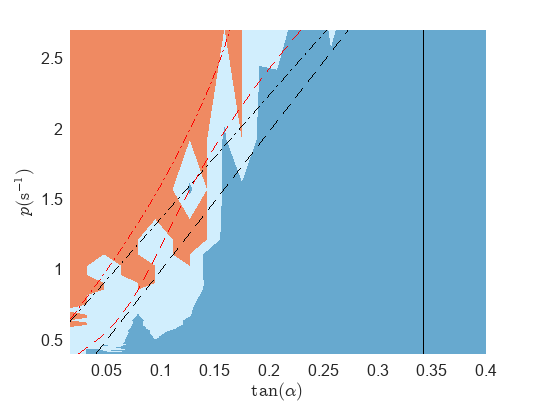

v = [0, 0];

figure

hold on

% For Ground Motion No. 1
load SpectraOutput\1.mat
R = reshape(data(:,1),[49,50]);
a = reshape(data(:,2),[49,50]);
t_a = reshape(data(:,4),[49,50]);
p = sqrt(12 * 9.81 ./ (15 + cos(a).*cos(a)) ./ R);
x = tan(a);
y = p;
contourf(x, y, t_a, [0, 1e-8, 0.3, 1], 'LineStyle', ':', 'EdgeColor','None')
colormap(flipud(othercolor('RdBu3')))

xGrid = 20;

[x1Grid,x2Grid] = meshgrid(linspace(0.0157, 1, xGrid),...
    linspace(0.3836, 3, xGrid));

xList = zeros(xGrid^2, 29);
xList(:, 28) = x1Grid(:); % tana
xList(:, 29) = x2Grid(:); % p

xList(:, 1) = 3.3599; % PGA
xList(:, 5) = IMs(1, 3); % PGV_FN
xList(:, 6) = IMs(1, 4); % PGD_FN
xList(:, 14) = IMs(1, 12); % apTp2
xList(:, 27) = 12 * 9.806 ./ ...
    (15 + cos(atan(xList(:, 28))).^2) ./ xList(:, 29).^2; % R

surface_data = array2table(xList, 'VariableNames', {'PGA', 'PGV', 'PGD', 'PGA_FN', 'PGV_FN', 'PGD_FN', 'PGVPGA_FN', 'A_RMS_FN', 'V_RMS_FN', 'D_RMS_FN', 'Arias_FN', 'SED_FN', 'CAV_FN', 'apTp2', 'T_m_FN', 'PGA_FP', 'PGV_FP', 'PGD_FP', 'PGVPGA_FP', 'A_RMS_FP', 'V_RMS_FP', 'D_RMS_FP', 'Arias_FP', 'SED_FP', 'CAV_FP', 'T_m_FP', 'R', 'tana', 'p'});
[~, scores_linear_0_3] = linear_0_3.predictFcn(surface_data);
[~, scores_linear_1_0] = linear_1_0.predictFcn(surface_data);
[~, scores_quadratic_0_3] = quadratic_0_3.predictFcn(surface_data);
[~, scores_quadratic_1_0] = quadratic_1_0.predictFcn(surface_data);
ZGrid_linear_0_3 = reshape(scores_linear_0_3(:,2), size(x1Grid));
ZGrid_linear_1_0 = reshape(scores_linear_1_0(:,2), size(x1Grid));

ZGrid_quadratic_0_3 = reshape(scores_quadratic_0_3(:,2), size(x1Grid));
ZGrid_quadratic_1_0 = reshape(scores_quadratic_1_0(:,2), size(x1Grid));

plot([xList(1, 1), xList(1, 1)]/9.81, [0.3836, 2.7545], 'k-')
contour(x1Grid, x2Grid, ZGrid_linear_0_3, v, 'k--')
contour(x1Grid, x2Grid, ZGrid_linear_1_0, v, 'k-.')
contour(x1Grid, x2Grid, ZGrid_quadratic_0_3, v, 'r--')
contour(x1Grid, x2Grid, ZGrid_quadratic_1_0, v, 'r-.')

xlim([pi/200, 0.4])
ylim([0.4, 2.7])
xlabel('$\rm tan(\it{\alpha} \rm)$','Interpreter','latex','FontName','times new roman')
ylabel('$p \rm (s^{-1})$', 'Interpreter', 'latex')
box on